# Signal Processing Coursework 

**Signal ID: 69**

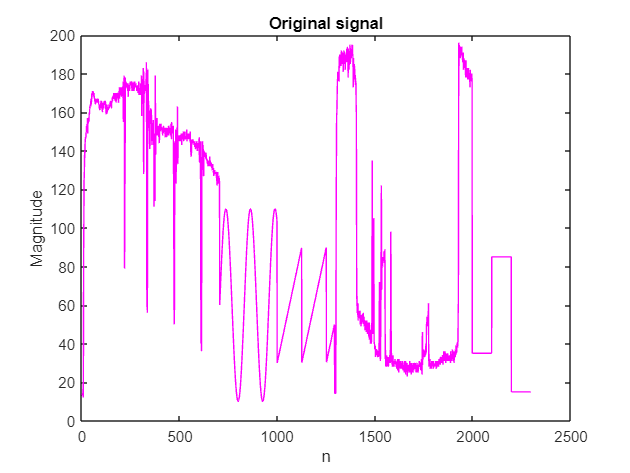

plot(signal,'m');
xlabel("n");
ylabel("Magnitude");
title('Original signal');

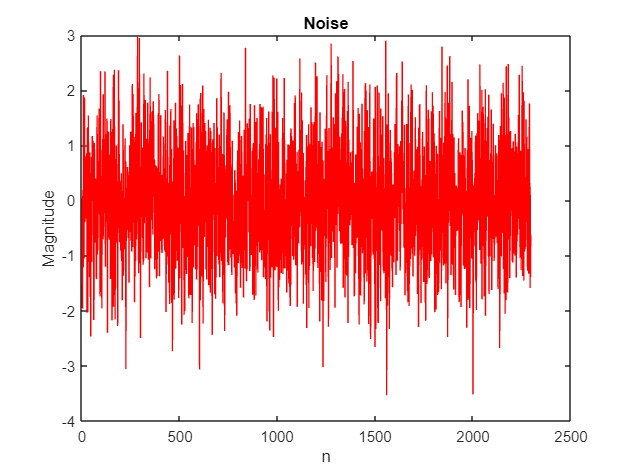

plot(noise,'r');
xlabel("n");
ylabel("Magnitude");
title("Noise");

Determine time domain and frequency domain of the original signal. 

**Adding two signals together **

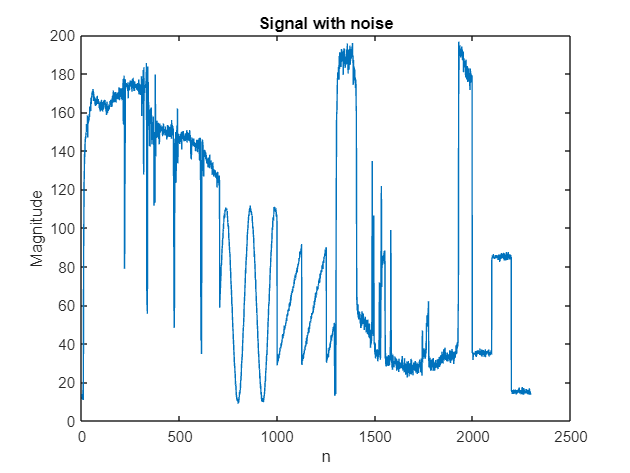

NoisySig= signal+noise;
plot(NoisySig);
ylabel("Magnitude");
xlabel("n");
title('Signal with noise');

### Time domain properties 

Apply difference filter to identify the edges (differences between adjecent values). 

Time domain allows seeing how signal varies accross the time. The in-built diff function calculates differences between adjacent elements of signal. It is clearly visible that there are quite a few edges and many homogenous regions. 

Therefore to identify all edges and divide signal into smaller segments of similar time-domain properties, find function was utilised. 

Important to note, DiffFilter's lenght (number of values) is smaller by one compare to signal's length. It's important to bear that in mind when dividing into segments. 

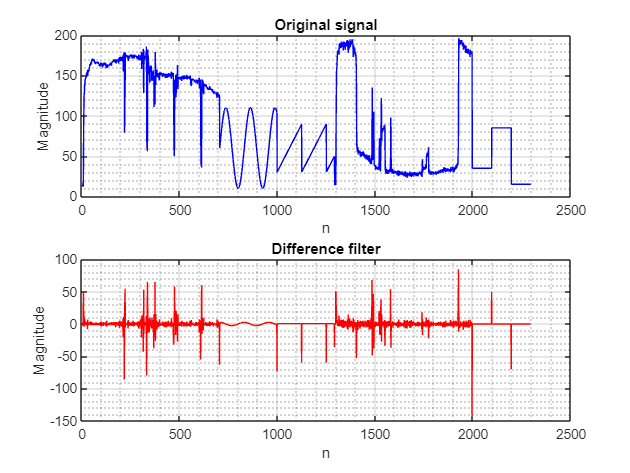

%Samples = length(signal); %get number of samples in the signal
DiffFilter = diff(signal); %apply difference filter 
figure
subplot(2,1,1);
plot(signal,"b");
xlabel("n");
ylabel("Magnitude");
grid on;
grid minor;
title("Original signal");

subplot(2,1,2);
plot(DiffFilter, "r");

grid on;
grid minor;
xlabel("n");
ylabel("Magnitude");
title("Difference filter");

#### Edges 

Find function to identify all edges. It looks for all the values within DiffFilter with its absolute values greater than the specified threshold and locates all the spikes. 

**(Double check how to specify the threshold name with lecturer)**

Threshold = 60; %threshold to specify from what values to identify the edges
Spikes = find(abs(DiffFilter)>Threshold);
%plot(Spikes);
%grid on; 
%grid minor;

First rapid spikes observed at 217 

First segment - homogenous region, between 1-217 locations so **first edge 217**

few spikes then up to **704** location - another homogenous region 

then no spikes up to **998**

another region - up to **1292**

then quite a few spikes up to **1581**

then another big spike is **1996**

and then up to the end 

**Remove the DC component to see other values - first and last values of the signal. Just for visualisation **

**can add threshold - higher just to show it's automated **

**Evaluate different lenghts and different number of passees. Just call it few times to a same signal. Show improvement. At some point it gets worse - evaluate it. **

**MSE is not good because one spike and the rest is fine and it does not give you great results. Can add it in conclusions **

### Frequency domain properties 

Extract segments from the original signal



segments = cell(1,7); % Create a cell array with 7 elements (one for each segment)
segments{1} = signal(1:217); 
segments{2} = signal(218:705); 
segments{3} = signal(706:998);
segments{4} = signal(999:1292);
segments{5} = signal(1293:1581);
segments{6} = signal(1582:1996);
segments{7} = signal(1997:end);

%create cell to store noisysegments 
NoisySegments = cell(1,7);
NoisySegments{1} = NoisySig(1:217);
NoisySegments{2} = NoisySig(218:705);
NoisySegments{3} = NoisySig(706:998);
NoisySegments{4} = NoisySig(999:1292);
NoisySegments{5} = NoisySig(1293:1581);
NoisySegments{6} = NoisySig(1582:1996);
NoisySegments{7} = NoisySig(1997:end);


**Update the lengths **

FFT - frequency domain properties 

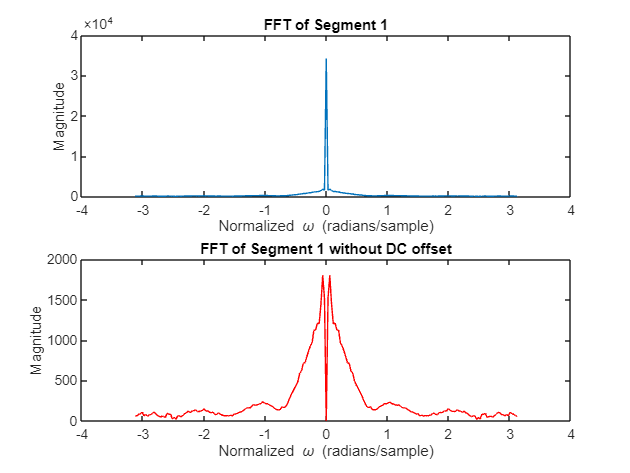

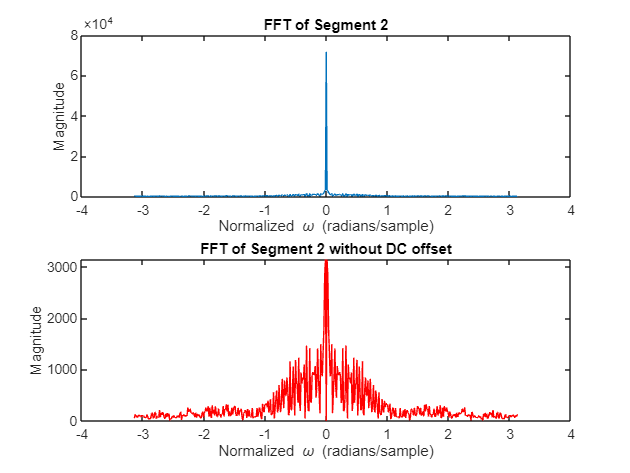

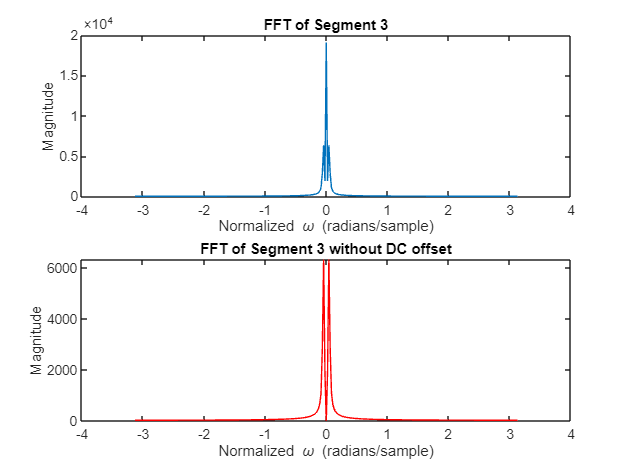

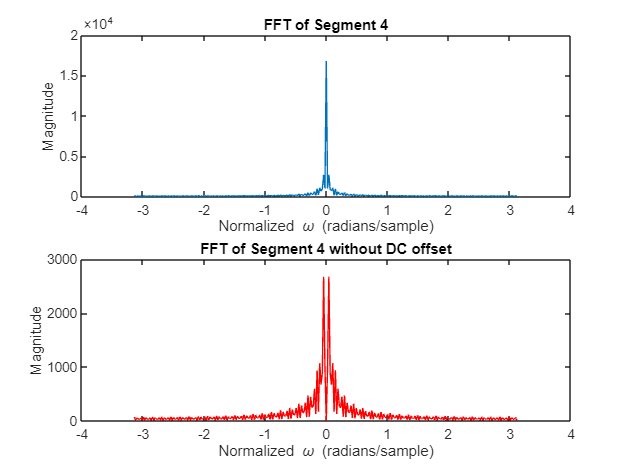

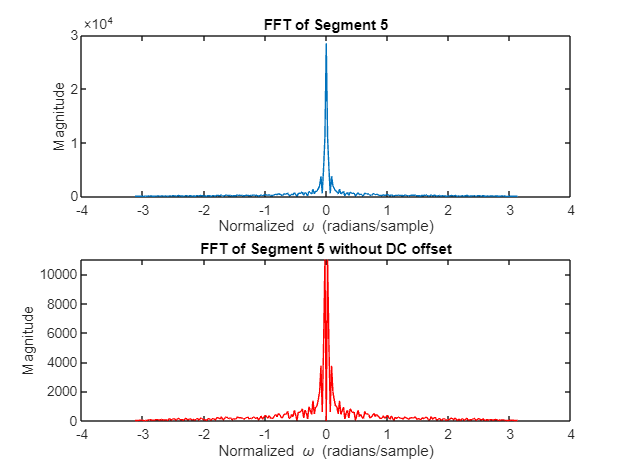

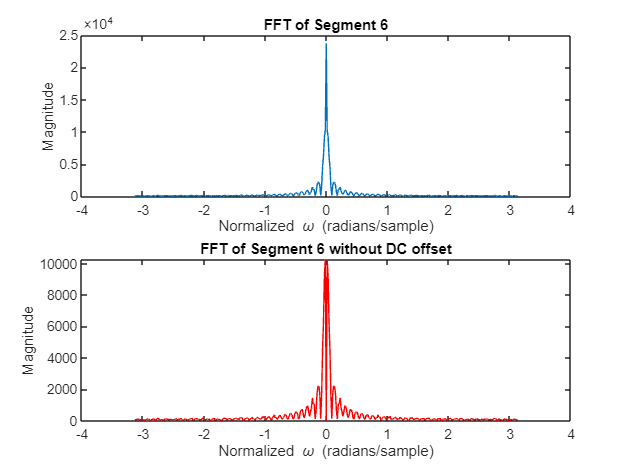

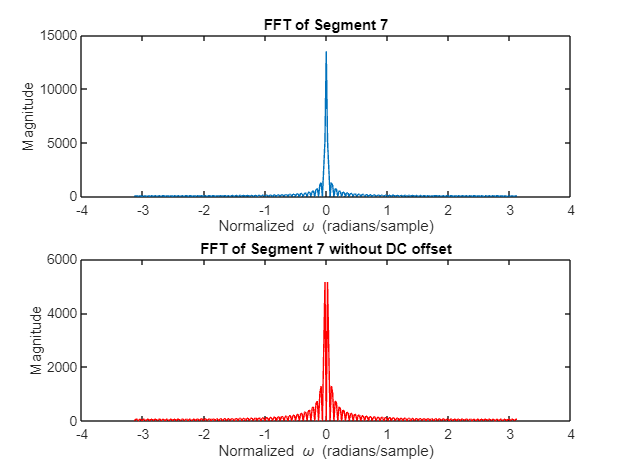

numSegments = 7;

% Create cell arrays to store FFT and f values for each segment
f = cell(1, numSegments);
FT = cell(1, numSegments);
f_noDC = cell(1, numSegments);
FT_noDC = cell(1, numSegments);

% Loop through each segment in the cell array
for segmentIdx = 1:numSegments
  segment = segments{segmentIdx}; % Access the current segment

  % Perform calculations for the current segment
  [f{segmentIdx}, FT{segmentIdx}] = NiceFFT(segment);
  [f_noDC{segmentIdx}, FT_noDC{segmentIdx}] = FFT_noDC(segment);

  figure
  subplot(2,1,1)
  plot(f{segmentIdx},abs(FT{segmentIdx}));
  title(sprintf("FFT of Segment %d", segmentIdx));
  xlabel("Normalized \omega (radians/sample)");
  ylabel("Magnitude");

  subplot(2,1,2)
  plot(f_noDC{segmentIdx},abs(FT_noDC{segmentIdx}),'r');
  title(sprintf("FFT of Segment %d without DC offset", segmentIdx));
  xlabel("Normalized \omega (radians/sample)");
  ylabel("Magnitude");
end

The presence of strong frequency components in the signal is indicated by the highest spikes. The prominence of these spikes suggests that certain frequencies in the signal are considerably stronger than others. The dominant frequency component in the signal is close to 0 Hz or DC (direct current) if there is most density around the 0 point of the FFT. A strong low-frequency or DC component in the signal can imply the existence of a significant offset or bias in practical terms. In signal processing, a strong low-frequency component might indicate a trend or baseline in the data.

From FFT can be seen very low frequencies are dominant for all segments so MAF is good as it preserves very low frequencies well and attenuates high frequencies 

DC offset 

DC offset, in the context of signals, refers to a constant voltage or current value that gets added to a signal that otherwise alternates around zero. It's essentially a bias that shifts the entire signal up or down on the vertical axis.

**Causes of DC Offset:**

- Imperfect electronic components:  Electronic components like capacitors can leak a small amount of DC current, introducing an offset.

- Faulty equipment:  Damaged cables or malfunctioning devices can introduce DC offset.

- Signal coupling:  In some cases, unwanted DC voltage from other sources can couple into your signal.

## Feedback 

 Then use the frequency domain properties of the signal segments to determine which length of MAFs should be applied on these segments. You so not have to concatenate the segments back to form the original signal. You should compute the MSE for segments separately and plot segments separately.

**Remove the DC component to see other values - first and last values of the signal. Just for visualisation **

**can add threshold - higher just to show it's automated **

**Evaluate different lenghts and different number of passees. Just call it few times to a same signal. Show improvement. At some point it gets worse - evaluate it. **

**MSE is not good because one spike and the rest is fine and it does not give you great results. Can add it in conclusions **

This is the whole point of this assignment and this is an excellent question.

Firstly make sure you compute the MSE for segments not for the whole signal.  The lower the MSE the similar the recovered signal to the original signal. But lower the MSE does not mean that all noise is removed. After doing this assignment you will realise the method you apply does not only remove noise, it will also modify the original signal. So, to have a lower MSE, the method must remove noise and it must not modify the original signal features. When you look at the frequency domain properties of the signal segments you will see that for some segments, your methods cannot preserve all the signal components. Therefore you will see an increase in MSE  for some segments.

Also make sure the increase in MSE is not due to an error in your implementation.

### MSE 

In signal processing, the mean squared error (MSE) is a metric used to quantify the difference between an estimated signal (your processed or filtered signal) and the original desired signal. It reflects how closely your processing matches the ideal outcome.

- **Lower MSE is generally better:** It signifies a closer match between the original and processed signal.

- **There's usually a trade-off:**  Achieving very low MSE might require complex processing or be limited by inherent noise in the signal.

**Moving average lenght and numbe rof passes**

**Boundary Effects in Moving Average Filters:**

When applying a moving average filter, the filter window needs to consider data points beyond the current point to calculate the average. This creates a challenge at the beginning and end (boundaries) of the signal where there aren't enough data points on one side of the current point to fill the entire window.

**Impact on Accuracy:**

Including the boundary points in the average would introduce inaccurate values:

- The first few data points would be averaged with nonexistent values before the signal starts.

- The last few data points would be averaged with nonexistent values after the signal ends.

#### 1st segment 

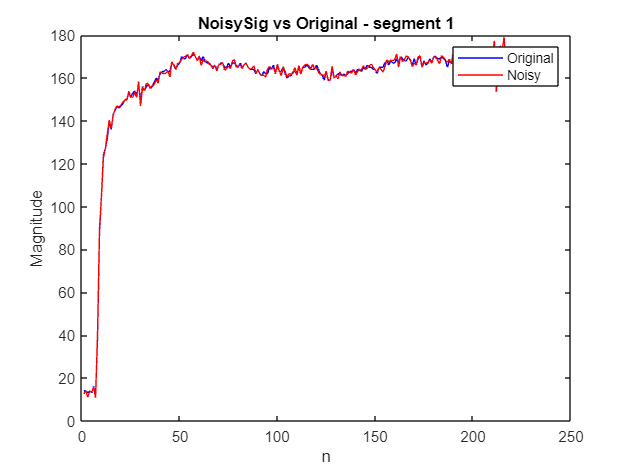

figure
plot(segments{1},'b');
hold on; 
plot(NoisySegments{1},'r');
xlabel("n");
ylabel("Magnitude");
title ('NoisySig vs Original - segment 1');
legend('Original','Noisy');

#### MSE and MAEs noisy signals

%MSE 
for index = 1:length(NoisySegments)
MSENoisy{index} = mean((NoisySegments{index}-segments{index}).*(NoisySegments{index}-segments{index}));
MAENoisy{index} = sum(abs(NoisySegments{index}-segments{index}))/length(NoisySegments{index});
end

MSENoisy = cell2mat(MSENoisy);


#### MAF and MSEs and MAEs calculations 

 

 [MAFFilteredSegment1,MSEFiltered1,MAEFiltered1] = MAF_filter(NoisySegments{1},segments{1},20,5);
 [MAFFilteredSegment2,MSEFiltered2,MAEFiltered2] = MAF_filter(NoisySegments{2},segments{2},20,5);
 [MAFFilteredSegment3,MSEFiltered3,MAEFiltered3] = MAF_filter(NoisySegments{3},segments{3},20,5);
 [MAFFilteredSegment4,MSEFiltered4,MAEFiltered4] = MAF_filter(NoisySegments{4},segments{4},20,5);
 [MAFFilteredSegment5,MSEFiltered5,MAEFiltered5] = MAF_filter(NoisySegments{5},segments{5},20,5);
 [MAFFilteredSegment6,MSEFiltered6,MAEFiltered6] = MAF_filter(NoisySegments{6},segments{6},20,5);
 [MAFFilteredSegment7,MSEFiltered7,MAEFiltered7] = MAF_filter(NoisySegments{7},segments{7},20,5);



#### MAEs

### MAF Performance analysis 

#### Segment1

  [MSE1Table] = MSE_MAE_Table(MSEFiltered1);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1     M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    0.98199    4.7485    7.9723    12.654    19.089    24.304    25.698    21.114    21.911    25.615
    N = 2    0.98199    5.2315    10.707    18.423    26.328    30.436    33.757    38.337     49.12    54.098
    N = 3    0.98199    6.9886    14.551    24.498    32.373    37.098    45.016    58.963    77.342    81.846
    N = 4   

  writetable(MSE1Table,'MSE1Table.xls');
  [MAE1Table] = MSE_MAE_Table(MAEFiltered1);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1     M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    0.76795     1.458     1.535     1.723    1.9596    2.0586    2.0513    1.9749    2.0467     2.155
    N = 2    0.76795    1.3471    1.6424    1.9675    2.2012    2.3364    2.4273    2.5426    2.7892    2.9122
    N = 3    0.76795    1.4928    1.8374    2.1948    2.4518    2.6222    2.8027    3.0536    3.4207     3.535
    N = 4   

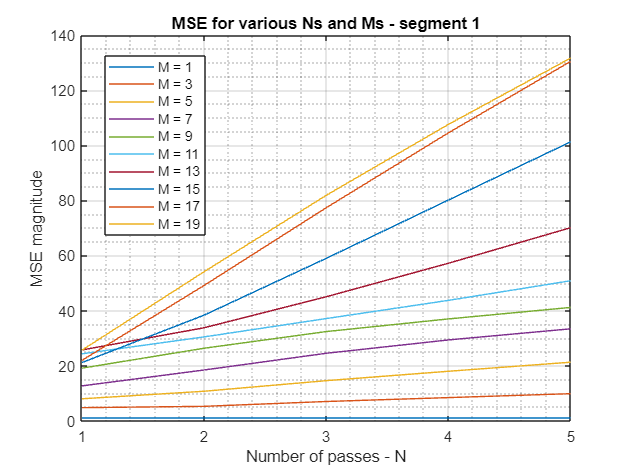

  writetable(MAE1Table,'MAE1Table.xls');
  N = [1,2,3,4,5];

  Title = "segment 1";
  MSEPlot(MSE1Table, N, Title);

Plots vs original signal

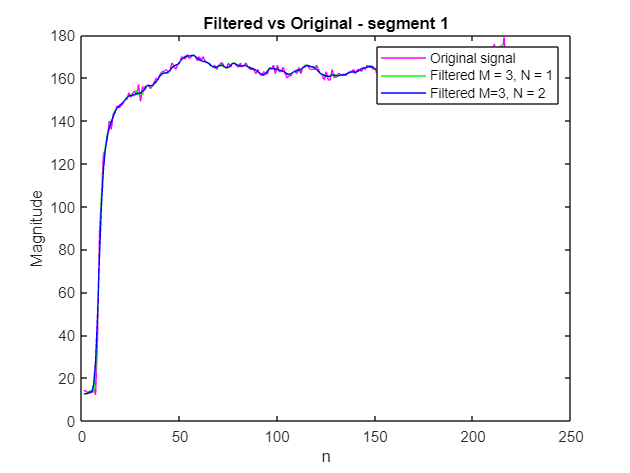

  figure;
  plot(segments{1},'m');
  hold on;
  plot(MAFFilteredSegment1{1,3},'g');
  plot(MAFFilteredSegment1{2,3},'b');

  legend( 'Original signal','Filtered M = 3, N = 1','Filtered M=3, N = 2');
  xlabel("n");
  ylabel("Magnitude");
  title ('Filtered vs Original - segment 1');

FFT 

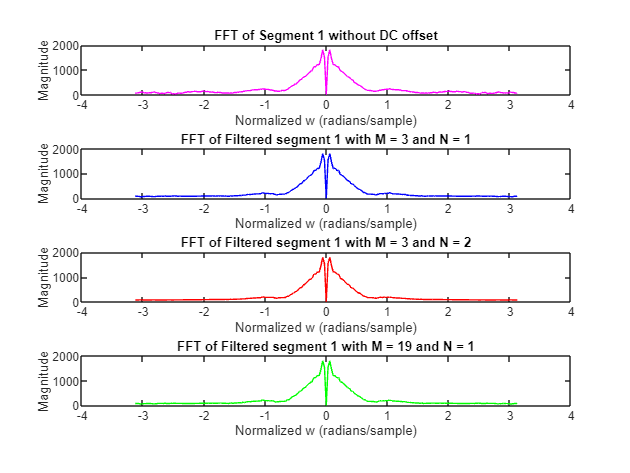

  %Create empty cells 
  FFTFiltered1_noDC = {}; f_filtered1_noDC = {};
  [f_filtered1_noDC{1}, FFTFiltered1_noDC{1}] = FFT_noDC(MAFFilteredSegment1{1,3});
  [f_filtered1_noDC{2}, FFTFiltered1_noDC{2}] = FFT_noDC(MAFFilteredSegment1{2,3});
    [f_filtered1_noDC{3}, FFTFiltered1_noDC{3}] = FFT_noDC(MAFFilteredSegment1{1,19});
  %plot everything together 
  figure;
  subplot(4,1,1);
  FFT_plot_MAF("FFT of Segment 1 without DC offset",FT_noDC{1},f_noDC{1},'m');
  subplot(4,1,2);
  FFT_plot_MAF("FFT of Filtered segment 1 with M = 3 and N = 1",FFTFiltered1_noDC{1},f_filtered1_noDC{1},'b');
  subplot(4,1,3);
  FFT_plot_MAF("FFT of Filtered segment 1 with M = 3 and N = 2",FFTFiltered1_noDC{2},f_filtered1_noDC{2},'r');
  subplot(4,1,4);
  FFT_plot_MAF("FFT of Filtered segment 1 with M = 19 and N = 1",FFTFiltered1_noDC{1},f_filtered1_noDC{1},'g');

High frequency components are not very well preserved - areas of -3 and 3 for the FFT - look flat 

Filter preserves overall shape of the signal a but does not do well with rapid changes 

Frequency response 

It preserves very low frequencies and attenuates high frequencies 

The more the passes the flatter the high frequency bands 

MAE can say that used it to compare the results of MSE 

Form the spikes (edges) it could have been seen that in this section there are many rapid changes = noisy signal and high frequency changes 

the higher the lenght (number of points) the more frequencies are attenuated 

More points - narrower band 

**Signal Distortion:** MAFs can introduce distortion to the signal, especially at sharp edges or transients (sudden changes in the signal). This smoothing effect can obscure important details in the data.

#### Segment 2 - the most noisy signal 

many large spikes - non homogenous segment and hence MSE quite high 

  [MSE2Table] = MSE_MAE_Table(MSEFiltered2);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
             M = 1    M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _____    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    1.034    23.362    50.045    76.126    112.71    148.25    178.46    199.04    212.43    221.39
    N = 2    1.034    30.797    64.359    105.84    141.69    162.68    178.88    191.13    200.83    208.71
    N = 3    1.034    41.221    86.471    131.74    167.55    185.86    200.59    211.59    220.03    226.83
    N = 4    1.034    

  writetable(MSE2Table,'MSE2Table.xls');
  [MAE2Table] = MSE_MAE_Table(MAEFiltered2);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1     M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    0.82351    2.5502    3.3057    4.0089    4.7034    5.3225    5.8736    6.1996    6.3691     6.491
    N = 2    0.82351    2.6671    3.7201    4.6528    5.3726    5.7258    5.9725    6.1484    6.2646    6.3611
    N = 3    0.82351     3.072    4.2774    5.1905    5.8416    6.1234    6.3135    6.4478    6.5512    6.6305
    N = 4   

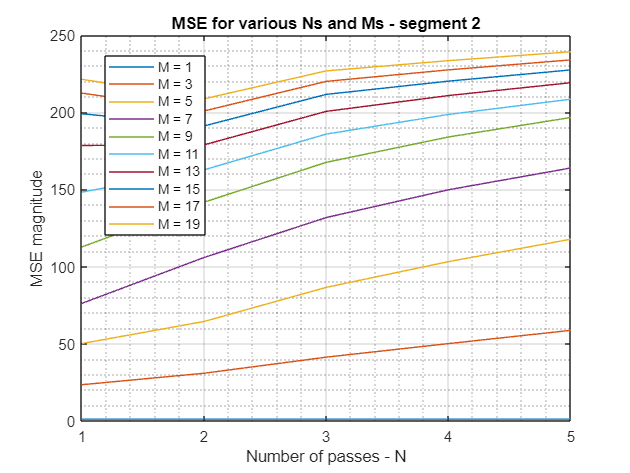

  writetable(MAE2Table,'MAE2Table.xls');
  N = [1,2,3,4,5];

  Title = "segment 2";
  MSEPlot(MSE2Table, N, Title);

Plots vs original signal

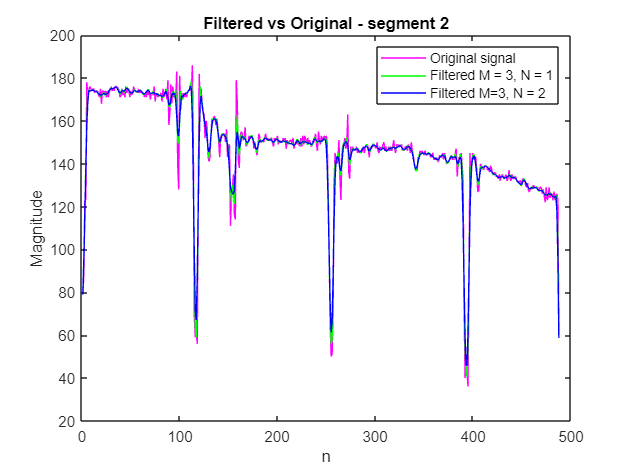

  figure;
  plot(segments{2},'m');

  hold on;
  plot(MAFFilteredSegment2{1,3},'g');
  plot(MAFFilteredSegment2{2,3},'b');
  legend('Original signal','Filtered M = 3, N = 1','Filtered M=3, N = 2');
  xlabel("n");
  ylabel("Magnitude");
  title ('Filtered vs Original - segment 2');

FFT

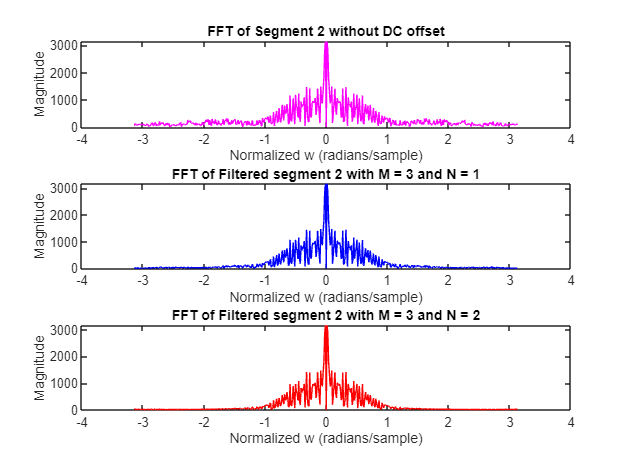

   %Create empty cells 
  FFTFiltered2_noDC = {}; f_filtered2_noDC = {};
  [f_filtered2_noDC{1}, FFTFiltered2_noDC{1}] = FFT_noDC(MAFFilteredSegment2{1,3});
  [f_filtered2_noDC{2}, FFTFiltered2_noDC{2}] = FFT_noDC(MAFFilteredSegment2{2,3});
  %plot everything together 
  figure;
  subplot(3,1,1);
  FFT_plot_MAF("FFT of Segment 2 without DC offset",FT_noDC{2},f_noDC{2},'m');
  subplot(3,1,2);
  FFT_plot_MAF("FFT of Filtered segment 2 with M = 3 and N = 1",FFTFiltered2_noDC{1},f_filtered2_noDC{1},'b');
  subplot(3,1,3);
   FFT_plot_MAF("FFT of Filtered segment 2 with M = 3 and N = 2",FFTFiltered2_noDC{2},f_filtered2_noDC{2},'r');

#### Segment 3 - sinusoidal 

  [MSE3Table] = MSE_MAE_Table(MSEFiltered3);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
             M = 1      M = 3      M = 5      M = 7      M = 9     M = 11     M = 13     M = 15     M = 17    M = 19
             ______    _______    _______    _______    _______    _______    _______    _______    ______    ______

    N = 1    0.9986    0.33066    0.21311     0.1683    0.18157    0.25576    0.40772    0.68504     1.083    1.6454
    N = 2    0.9986    0.22811    0.15874    0.19532    0.37262    0.74539      1.405     2.4527    3.9867    6.1321
    N = 3    0.9986    0.18649    0.16243      0.312    0.74856      1.606     3.0791     5.3424    8.6367    13.183

  writetable(MSE3Table,'MSE3Table.xls');
  [MAE3Table] = MSE_MAE_Table(MAEFiltered3);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1      M = 3      M = 5      M = 7      M = 9     M = 11     M = 13     M = 15     M = 17     M = 19
             _______    _______    _______    _______    _______    _______    _______    _______    _______    ______

    N = 1    0.82526    0.46578    0.36231     0.3254    0.34316    0.41211    0.53862    0.71915    0.92253    1.1468
    N = 2    0.82526    0.38384    0.31781    0.35801    0.51297    0.75558     1.0572     1.4041     1.7908    2.2168
    N = 3    0.82526    0.34685    0.32485     0.4631    0.75732     1.1318     1.5744     2.0725     2.6284

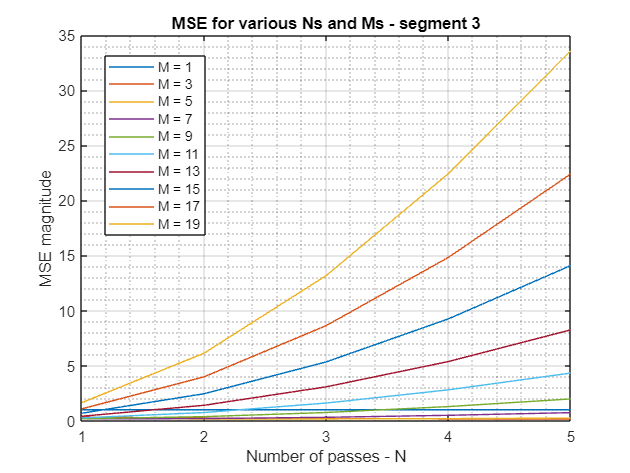

  writetable(MAE3Table,'MAE3Table.xls');
  N = [1,2,3,4,5];

  Title = "segment 3";
  MSEPlot(MSE3Table, N, Title);

Plots vs original signal

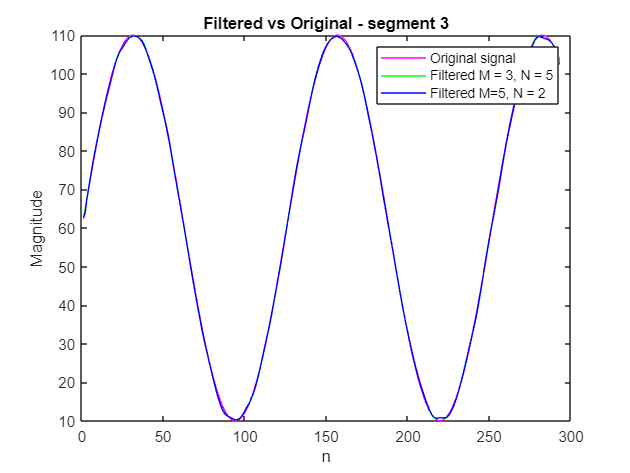

  figure;
  plot(segments{3},'m');

  hold on;
  plot(MAFFilteredSegment3{5,3},'g');
  plot(MAFFilteredSegment3{2,5},'b');
  legend('Original signal','Filtered M = 3, N = 5','Filtered M=5, N = 2');
  xlabel("n");
  ylabel("Magnitude");
  title ('Filtered vs Original - segment 3');

FFT 

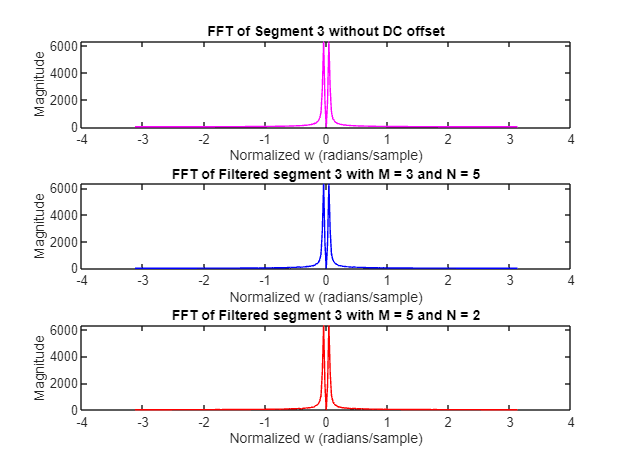

    %Create empty cells 
  FFTFiltered3_noDC = {}; f_filtered3_noDC = {};
  [f_filtered3_noDC{1}, FFTFiltered3_noDC{1}] = FFT_noDC(MAFFilteredSegment3{5,3});
  [f_filtered3_noDC{2}, FFTFiltered3_noDC{2}] = FFT_noDC(MAFFilteredSegment3{2,5});
  %plot everything together 
  figure;
  subplot(3,1,1);
  FFT_plot_MAF("FFT of Segment 3 without DC offset",FT_noDC{3},f_noDC{3},'m');
  subplot(3,1,2);
  FFT_plot_MAF("FFT of Filtered segment 3 with M = 3 and N = 5",FFTFiltered3_noDC{1},f_filtered3_noDC{1},'b');
  subplot(3,1,3);
   FFT_plot_MAF("FFT of Filtered segment 3 with M = 5 and N = 2",FFTFiltered3_noDC{2},f_filtered3_noDC{2},'r');

#### Segment 4 - ramp

   [MSE4Table] = MSE_MAE_Table(MSEFiltered4);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1     M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    0.94574    5.6678    10.148     14.19    18.275    22.345    26.421    30.489    34.504    38.555
    N = 2    0.94574    6.2746    11.618    16.692     21.66    26.566     31.49     36.46    41.413    46.378
    N = 3    0.94574    8.0706    14.432    20.497    26.482    32.472    38.482    44.526    50.551    56.586
    N = 4   

  writetable(MSE4Table,'MSE4Table.xls');
  [MAE4Table] = MSE_MAE_Table(MAEFiltered4);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1      M = 3      M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    _______    _______    ______    ______    ______    ______    ______    ______    ______

    N = 1    0.77476    0.69693    0.83246    1.0056    1.1915    1.3728    1.5643    1.7627    1.9551    2.1496
    N = 2    0.77476    0.72124     0.9492    1.1905    1.4394    1.6918    1.9476    2.2211    2.4846    2.7536
    N = 3    0.77476    0.78268      1.075    1.3728    1.6759    1.9894    2.3098     2.647    2.9681    3.2989
    N = 4</

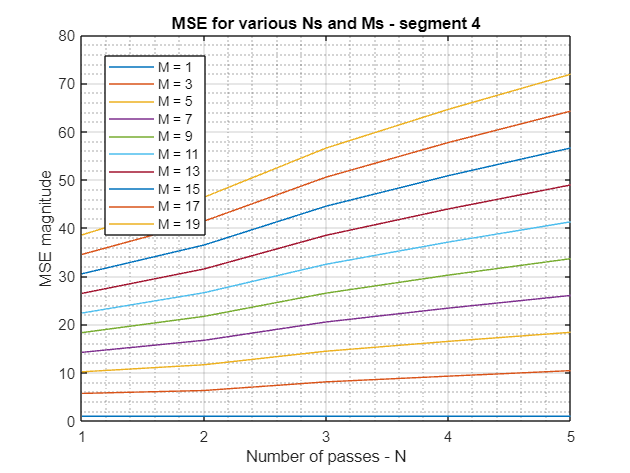

  writetable(MAE4Table,'MAE4Table.xls');
  N = [1,2,3,4,5];

  Title = "segment 4";
  MSEPlot(MSE4Table, N, Title);

Plots vs original signal

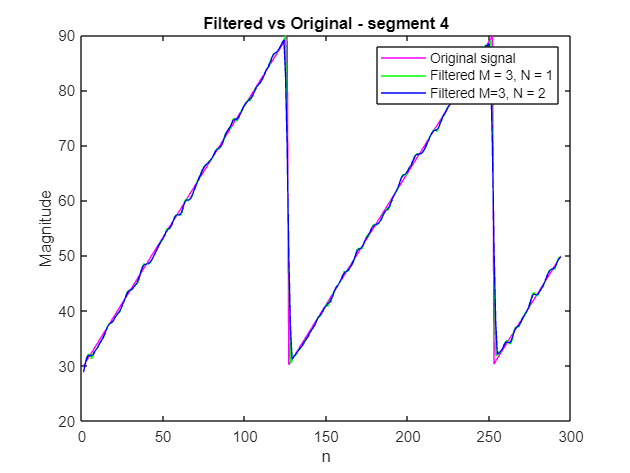

  figure;
  plot(segments{4},'m');

  hold on;
  plot(MAFFilteredSegment4{1,3},'g');
  plot(MAFFilteredSegment4{2,3},'b');
  legend('Original signal','Filtered M = 3, N = 1','Filtered M=3, N = 2');
  xlabel("n");
  ylabel("Magnitude");
  title ('Filtered vs Original - segment 4');

FFT 

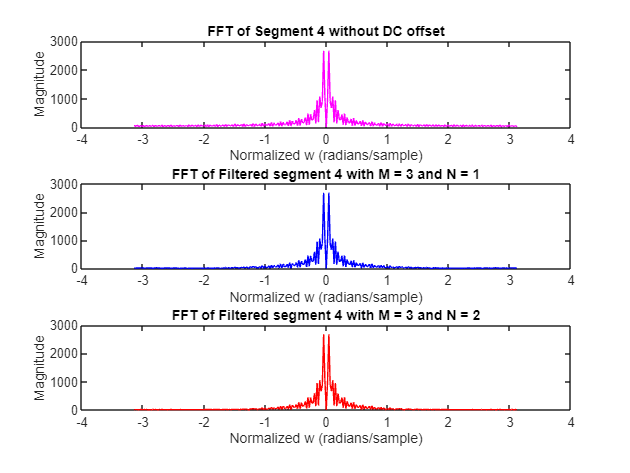

  %Create empty cells 
  FFTFiltered4_noDC = {}; f_filtered4_noDC = {};
  [f_filtered4_noDC{1}, FFTFiltered4_noDC{1}] = FFT_noDC(MAFFilteredSegment4{1,3});
  [f_filtered4_noDC{2}, FFTFiltered4_noDC{2}] = FFT_noDC(MAFFilteredSegment4{2,3});
  %plot everything together 
  figure;
  subplot(3,1,1);
  FFT_plot_MAF("FFT of Segment 4 without DC offset",FT_noDC{4},f_noDC{4},'m');
  subplot(3,1,2);
  FFT_plot_MAF("FFT of Filtered segment 4 with M = 3 and N = 1",FFTFiltered4_noDC{1},f_filtered4_noDC{1},'b');
  subplot(3,1,3);
   FFT_plot_MAF("FFT of Filtered segment 4 with M = 3 and N = 2",FFTFiltered4_noDC{2},f_filtered4_noDC{2},'r');

#### Segment 5 - noisy again

  [MSE5Table] = MSE_MAE_Table(MSEFiltered5);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
             M = 1     M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    1.1737    23.861    54.693    83.647    114.89    138.97    151.74    150.57    157.83    169.88
    N = 2    1.1737    33.256    69.731    103.51    127.79    144.22    161.43    181.59    208.23     226.5
    N = 3    1.1737    44.159     90.33    124.44    149.83    170.72    197.13    232.01    268.78     290.3
    N = 4    1.17

  writetable(MSE5Table,'MSE5Table.xls');
  [MAE5Table] = MSE_MAE_Table(MAEFiltered5);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1     M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    0.85613    2.8416    3.8031    4.7246    5.5919    6.1903     6.577    6.7539    7.0158    7.3336
    N = 2    0.85613    3.0704    4.4261    5.4612    6.1786    6.6855    7.1856    7.7217    8.3755    8.8717
    N = 3    0.85613    3.5306    5.0498    6.1049    6.8589    7.5004    8.1595    8.9207     9.792    10.424
    N = 4   

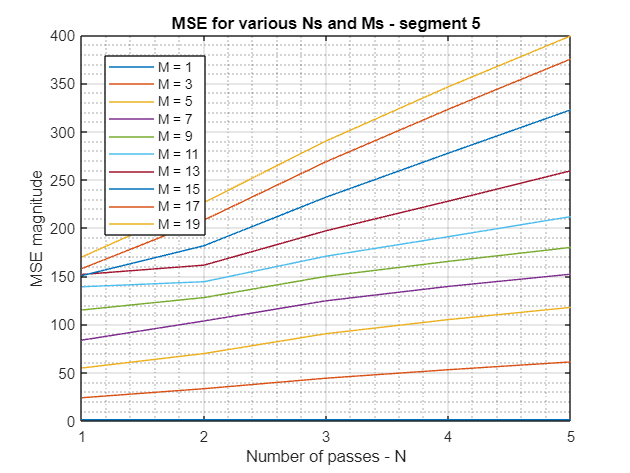

  writetable(MAE5Table,'MAE5Table.xls');
  N = [1,2,3,4,5];

  Title = "segment 5";
  MSEPlot(MSE5Table, N, Title);

Plots vs original signal

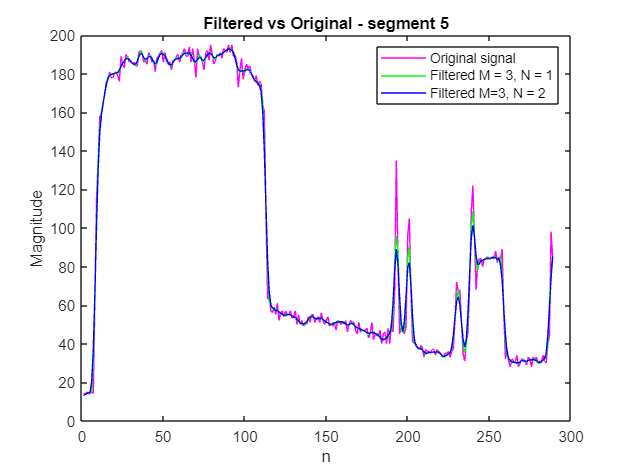

  figure;
  plot(segments{5},'m');

  hold on;
  plot(MAFFilteredSegment5{1,3},'g');
  plot(MAFFilteredSegment5{2,3},'b');
  legend('Original signal','Filtered M = 3, N = 1','Filtered M=3, N = 2');
  xlabel("n");
  ylabel("Magnitude");
  title ('Filtered vs Original - segment 5');

FFT 

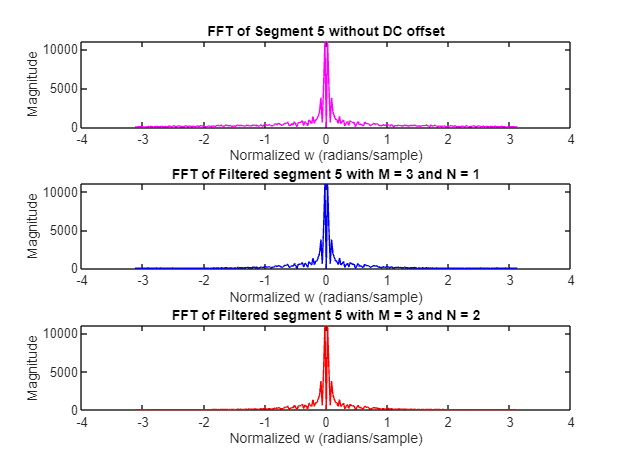

  %Create empty cells 
  FFTFiltered5_noDC = {}; f_filtered5_noDC = {};
  [f_filtered5_noDC{1}, FFTFiltered5_noDC{1}] = FFT_noDC(MAFFilteredSegment5{1,3});
  [f_filtered5_noDC{2}, FFTFiltered5_noDC{2}] = FFT_noDC(MAFFilteredSegment5{2,3});
  %plot everything together 
  figure;
  subplot(3,1,1);
  FFT_plot_MAF("FFT of Segment 5 without DC offset",FT_noDC{5},f_noDC{5},'m');
  subplot(3,1,2);
  FFT_plot_MAF("FFT of Filtered segment 5 with M = 3 and N = 1",FFTFiltered5_noDC{1},f_filtered5_noDC{1},'b');
  subplot(3,1,3);
   FFT_plot_MAF("FFT of Filtered segment 5 with M = 3 and N = 2",FFTFiltered5_noDC{2},f_filtered5_noDC{2},'r');

#### Segment 6 

  [MSE6Table] = MSE_MAE_Table(MSEFiltered6);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1     M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    0.96891     7.516    13.245     19.21    27.428    35.799    44.858    54.144    63.583    72.896
    N = 2    0.96891    8.2797    16.306    25.787    36.162    46.964    58.032    69.295     80.65     92.22
    N = 3    0.96891    10.703    21.254    33.402    46.447    59.929    73.686    87.723    101.89    116.28
    N = 4   

  writetable(MSE6Table,'MSE6Table.xls');
  [MAE6Table] = MSE_MAE_Table(MAEFiltered6);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1     M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    0.78817    1.7535    1.8032    1.9986    2.2637    2.4112    2.6481    2.8365    3.0522    3.2396
    N = 2    0.78817    1.5659    1.9102    2.2008    2.4742     2.747    3.0337    3.3258    3.6082    3.8874
    N = 3    0.78817    1.7164    2.0893    2.4201    2.7497    3.0968    3.4436    3.7877     4.116    4.4372
    N = 4   

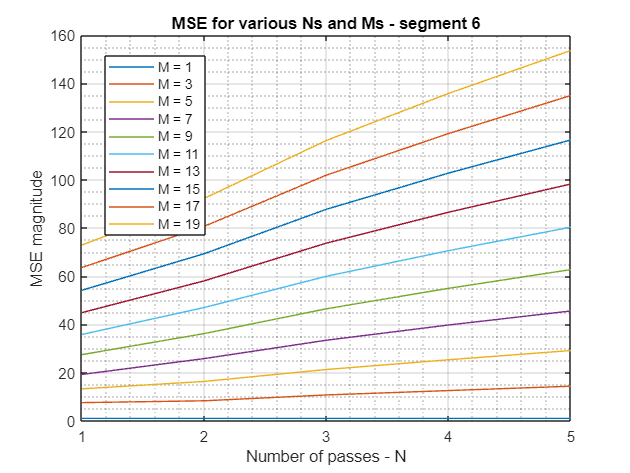

  writetable(MAE6Table,'MAE6Table.xls');
  N = [1,2,3,4,5];

  Title = "segment 6";
  MSEPlot(MSE6Table, N, Title);

Plots vs original signal

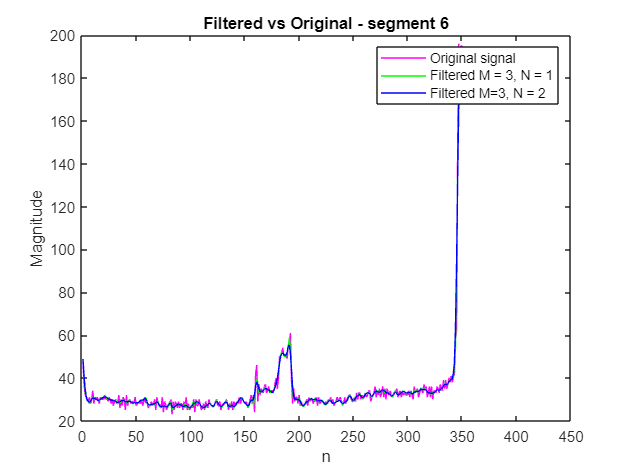

  figure;
  plot(segments{6},'m');

  hold on;
  plot(MAFFilteredSegment6{1,3},'g');
  plot(MAFFilteredSegment6{2,3},'b');
  legend('Original signal','Filtered M = 3, N = 1','Filtered M=3, N = 2');
  xlabel("n");
  ylabel("Magnitude");
  title ('Filtered vs Original - segment 6');

FFT

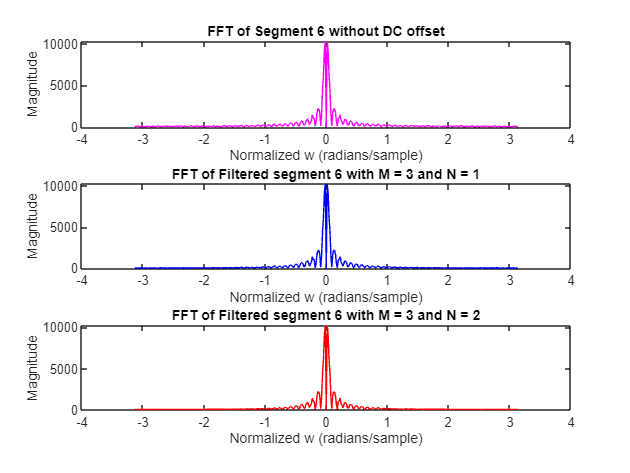

  %Create empty cells 
  FFTFiltered6_noDC = {}; f_filtered6_noDC = {};
  [f_filtered6_noDC{1}, FFTFiltered6_noDC{1}] = FFT_noDC(MAFFilteredSegment6{1,3});
  [f_filtered6_noDC{2}, FFTFiltered6_noDC{2}] = FFT_noDC(MAFFilteredSegment6{2,3});
  %plot everything together 
  figure;
  subplot(3,1,1);
  FFT_plot_MAF("FFT of Segment 6 without DC offset",FT_noDC{6},f_noDC{6},'m');
  subplot(3,1,2);
  FFT_plot_MAF("FFT of Filtered segment 6 with M = 3 and N = 1",FFTFiltered6_noDC{1},f_filtered6_noDC{1},'b');
  subplot(3,1,3);
   FFT_plot_MAF("FFT of Filtered segment 6 with M = 3 and N = 2",FFTFiltered6_noDC{2},f_filtered6_noDC{2},'r');

#### Segment 7 

  [MSE7Table] = MSE_MAE_Table(MSEFiltered7);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1     M = 3     M = 5     M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    N = 1    0.95029     5.831    10.176    14.221    18.441    22.682    26.759    30.776    34.822    38.911
    N = 2    0.95029    6.4143    11.742    16.896    21.897    26.893    31.834    36.787    41.751    46.727
    N = 3    0.95029     8.191    14.587    20.717    26.762    32.816    38.838    44.884    50.937    56.988
    N = 4   

  writetable(MSE7Table,'MSE7Table.xls');
  [MAE7Table] = MSE_MAE_Table(MAEFiltered7);

NotemptyCols =      1     3     5     7     9    11    13    15    17    19


CleanTable = 5×10 table
              M = 1      M = 3     M = 5      M = 7     M = 9     M = 11    M = 13    M = 15    M = 17    M = 19
             _______    _______    ______    _______    ______    ______    ______    ______    ______    ______

    N = 1    0.77373    0.70213    0.8083    0.94173    1.1031      1.29    1.4725    1.6647    1.8542     2.045
    N = 2    0.77373    0.71129    0.8967     1.1099     1.343    1.5997    1.8565    2.1211    2.3872    2.6535
    N = 3    0.77373    0.75972    1.0119     1.2796    1.5762    1.9024     2.226    2.5508    2.8787    3.2059
    N = 4</

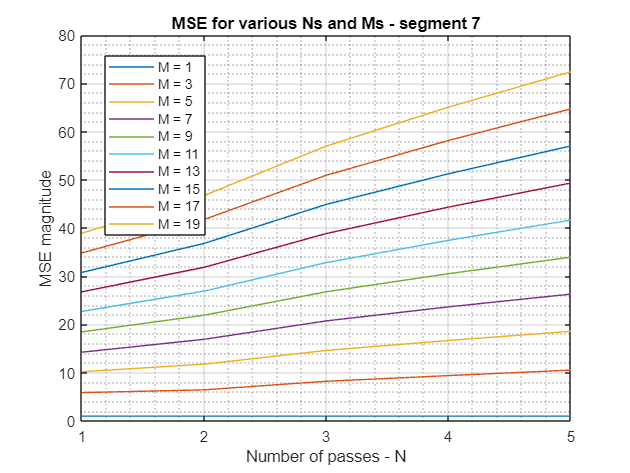

  writetable(MAE7Table,'MAE7Table.xls');
  N = [1,2,3,4,5];

  Title = "segment 7";
  MSEPlot(MSE7Table, N, Title);

Plots vs original signal

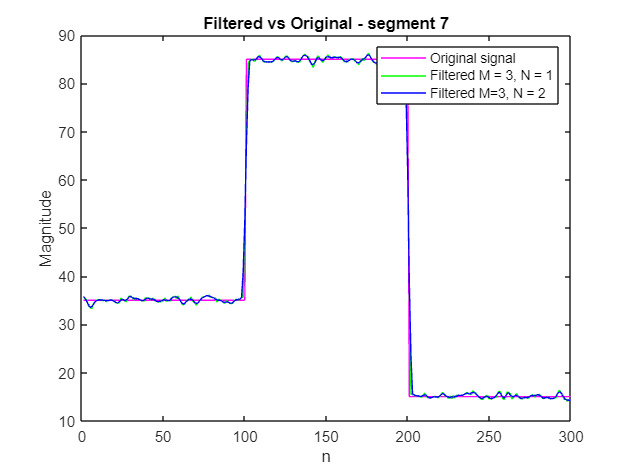

  figure;
  plot(segments{7},'m');

  hold on;
  plot(MAFFilteredSegment7{1,3},'g');
  plot(MAFFilteredSegment7{2,3},'b');
  legend('Original signal','Filtered M = 3, N = 1','Filtered M=3, N = 2');
  xlabel("n");
  ylabel("Magnitude");
  title ('Filtered vs Original - segment 7');

FFT

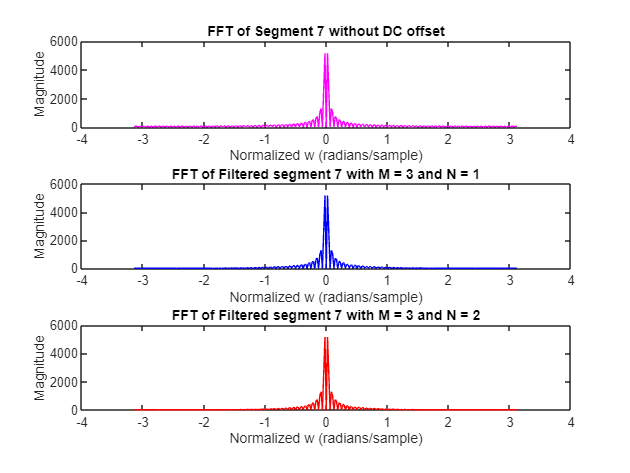

  %Create empty cells 
  FFTFiltered7_noDC = {}; f_filtered7_noDC = {};
  [f_filtered7_noDC{1}, FFTFiltered7_noDC{1}] = FFT_noDC(MAFFilteredSegment7{1,3});
  [f_filtered7_noDC{2}, FFTFiltered7_noDC{2}] = FFT_noDC(MAFFilteredSegment7{2,3});
  %plot everything together 
  figure;
  subplot(3,1,1);
  FFT_plot_MAF("FFT of Segment 7 without DC offset",FT_noDC{7},f_noDC{7},'m');
  subplot(3,1,2);
  FFT_plot_MAF("FFT of Filtered segment 7 with M = 3 and N = 1",FFTFiltered7_noDC{1},f_filtered7_noDC{1},'b');
  subplot(3,1,3);
   FFT_plot_MAF("FFT of Filtered segment 7 with M = 3 and N = 2",FFTFiltered7_noDC{2},f_filtered7_noDC{2},'r');

**For testing **

 %  %MSE 
% %create cells for MSEs 
% MSENoisy = cell(1,7);
% MSEFiltered = cell(4,15);
% 
% MSENoisy{1} = mean((NoisySegments{3}-segments{3}).*(NoisySegments{3}-segments{3})) 
% 
% %Create a cell to store filtered segments 
% MAFFilteredSegments = cell(4,15);
% 
% 
%  for M = 1:15 %loop for filter lenght
%      %Assign Noise to first cell so MAF can be calculated 
%      % MAFFilteredSegments{1,M} = NoisySegments{1};
%     %n = 2:length(NoisySegments{1});
%     for N=1:4 %loop for number of passes 
%         MAFFilteredSegments{N,M} = NoisySegments{3};
%         for i = 3:291 %loop to iterate through each value in the signal 
%             if N==1 
%              MAFFilteredSegments{N,M}(i) = (NoisySegments{3}(i-2) +NoisySegments{3}(i-1)+ NoisySegments{3}(i) + NoisySegments{3}(i+1)+NoisySegments{3}(i+2))/M;
%             else 
%              MAFFilteredSegments{N,M}(i) = (MAFFilteredSegments{N-1,M}(i-2)+MAFFilteredSegments{N-1,M}(i-1) +MAFFilteredSegments{N-1,M}(i) + MAFFilteredSegments{N-1,M}(i+1)+MAFFilteredSegments{N-1,M}(i+2))/M;
%             end
%         end
%         MSEFiltered{N,M} = mean((MAFFilteredSegments{N,M}-segments{3}).*(MAFFilteredSegments{N,M}-segments{3}));
%     end
%         % MSEFiltered{1,M} = mean((MAFFilteredSegments{1,M}-segments{1}).*(MAFFilteredSegments{1,M}-segments{1}))
% 
%  end